% Solution of the system of 11 equations for N atoms interaction with a
% cavity mode -  semi-classical approach!
echo off
clear all
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% DEFINING THE PARAMETERS FOR THIS SYSTEM (Hamiltonian): %%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Nat = 5;   % Number of atoms.
kappa = 1.0;

g = 10.0*kappa/sqrt(Nat);           % atom-field coupling: atomic transition 3<->1.
EM = sqrt(0.1)*kappa;          % probe field - the cavity mode -it'll be evaluated bellow!
Oc = 1.0*kappa;           % Rabi freq. control field (pumping - atomic transition 2 <-> 3.
D1 = 0.0;          % Detuning between the atom and the cavity mode (Delta1).
D2 = 0.0;          % Detuning between the atom and the control field (Delta2).
%%%%%%%% DEFINING THE DISSIPATIVE PARAMETERS - Decay rates: %%%%%%%%%%%%%%
Gamma31 = 0.5;     % Decay rate from the level 3 to level 1.
Gamma32 = 0.5;     % Decay rate from the level 3 to level 2.
gamma2  = 0.0;    % Dephasing rate -  level 2.
gamma3  = 0.0;    % Dephasing rate -  level 3.

% Varying Parameters
np = 101;  
Dp_list = linspace(-1.0,1.0,np)*kappa

Dp_list =    -1.0000   -0.9800   -0.9600   -0.9400   -0.9200   -0.9000   -0.8800   -0.8600   -0.8400   -0.8200   -0.8000   -0.7800   -0.7600   -0.7400   -0.7200   -0.7000   -0.6800   -0.6600   -0.6400   -0.6200   -0.6000   -0.5800   -0.5600   -0.5400   -0.5200   -0.5000   -0.4800   -0.4600   -0.4400   -0.4200   -0.4000   -0.3800   -0.3600   -0.3400   -0.3200   -0.3000   -0.2800   -0.2600   -0.2400   -0.2200   -0.2000   -0.1800   -0.1600   -0.1400   -0.1200   -0.1000   -0.0800   -0.0600   -0.0400   -0.0200


nsteps = 200;
TM = 10000;
t0 = 0;
tspan = linspace(t0, TM, nsteps)

tspan = 	1.0e+04 *

         0    0.0050    0.0101    0.0151    0.0201    0.0251    0.0302    0.0352    0.0402    0.0452    0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0854    0.0905    0.0955    0.1005    0.1055    0.1106    0.1156    0.1206    0.1256    0.1307    0.1357    0.1407    0.1457    0.1508    0.1558    0.1608    0.1658    0.1709    0.1759    0.1809    0.1859    0.1910    0.1960    0.2010    0.2060    0.2111    0.2161    0.2211    0.2261    0.2312    0.2362    0.2412    0.2462



y0 = [0 0 0 0 0 0 0 0 Nat 0 0];   % Initial condition: <sigma_ 11> = 1. -> <S11> = N*<sigma_ 11>.
hold on;

%%%%%%%% First loop: Varying probe detuning %%%%%%%%%%
for j = 1:length(Dp_list)
    
    Dp = Dp_list(j);          % Detuning between the probe field and the cavity mode.
    [t,Y] = ode45(@(t,y) semiclassical(t0, g, EM, Oc, D1, D2, Dp, Gamma31, Gamma32, gamma2, gamma3, kappa, t, y), tspan, [y0]);
    
    transmission(j) = real(Y(end,1)*Y(end,2))/(4*(EM/kappa)^2);
    
    fprintf('%d%%...',101.0*j/np);   %progress
end

1%...2%...3%...4%...5%...6%...7%...8%...9%...10%...11%...12%...13%...14%...15%...16%...17%...18%...19%...20%...21%...22%...23%...24%...25%...26%...27%...28%...29%...30%...31%...32%...33%...34%...35%...36%...37%...38%...39%...40%...41%...42%...43%...44%...45%...46%...47%...48%...49%...50%...51%...52%...53%...54%...55%...56%...57%...58%...59%...60%...61%...62%...63%...64%...65%...66%...67%...68%...69%...70%...71%...72%...73%...74%...75%...76%...77%...78%...79%...80%...81%...82%...83%...84%...85%...86%...87%...88%...89%...90%...91%...92%...93%...94%...95%...96%...97%...98%...99%...100%...101%...


plot(Dp_list, transmission);
Dp_list

Dp_list =    -1.0000   -0.9800   -0.9600   -0.9400   -0.9200   -0.9000   -0.8800   -0.8600   -0.8400   -0.8200   -0.8000   -0.7800   -0.7600   -0.7400   -0.7200   -0.7000   -0.6800   -0.6600   -0.6400   -0.6200   -0.6000   -0.5800   -0.5600   -0.5400   -0.5200   -0.5000   -0.4800   -0.4600   -0.4400   -0.4200   -0.4000   -0.3800   -0.3600   -0.3400   -0.3200   -0.3000   -0.2800   -0.2600   -0.2400   -0.2200   -0.2000   -0.1800   -0.1600   -0.1400   -0.1200   -0.1000   -0.0800   -0.0600   -0.0400   -0.0200


transmission

transmission =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0005    0.0006    0.0007    0.0009    0.0013    0.0017    0.0026    0.0043    0.0088    0.9665    0.9918


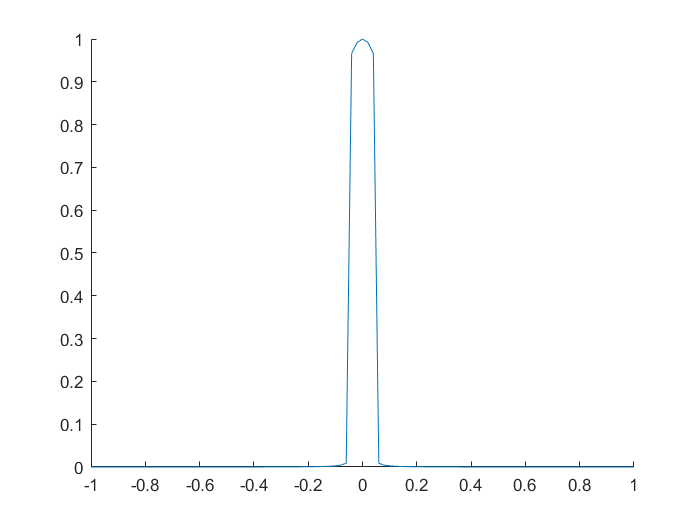

dlmwrite('C:\Users\lucas\Desktop\Semiclassical\integration\MatLab\semiclassical_intML_TS_Nat5_g10_ep01_Oc1.csv', [Dp_list(:),transmission(:)]);
hold off;

% System of differential equations for N atoms interacting with a cavity
% mode. However, considering a semi-classical approach, i.e., the cavity
% mode is classical. So, we solve the Maxwell-Bloch equations!


function dy = semiclassical(t0, g, EM, Oc, D1, D2, Dp, Gamma31, Gamma32, gamma2, gamma3, kappa, t, y)

    dy = zeros(11,1);    % a column vector
    dy(1) = 1i*(Dp+1i*(kappa/2))*y(1) - 1i*EM - 1i*g*y(5);    % <a>
    dy(2) = -1i*(Dp-1i*(kappa/2))*y(2) + 1i*EM + 1i*g*y(6);  % <a'>
        
    dy(3) = 1i*(Dp-(D1-D2)+1i*(gamma2/2))*y(3) +1i*g*y(1)*y(8) -1i*Oc*y(5);  % <S12>
    dy(4) = -1i*(Dp-(D1-D2)-1i*(gamma2/2))*y(4) -1i*g*y(2)*y(7) +1i*Oc*y(6); % <S21>
        
    dy(5) = 1i*(Dp-D1+(1i/2)*(Gamma31+Gamma32+gamma3))*y(5) -1i*g*y(1)*(y(9)-y(11)) - 1i*Oc*y(3);  % <S13>
    dy(6) = -1i*(Dp-D1-(1i/2)*(Gamma31+Gamma32+gamma3))*y(6) +1i*g*y(2)*(y(9)-y(11)) + 1i*Oc*y(4); % <S31>
        
    dy(8) = 1i*(D2+(1i/2)*(Gamma31+Gamma32+gamma2+gamma3))*y(8) +1i*g*y(2)*y(3)+1i*Oc*(y(10)-y(11));  % <S32>
    dy(7) = -1i*(D2-(1i/2)*(Gamma31+Gamma32+gamma2+gamma3))*y(7) -1i*g*y(1)*y(4)-1i*Oc*(y(10)-y(11)); % <S23>
        
    dy(9) = 1i*g*y(1)*y(6)-1i*g*y(2)*y(5)+2*(Gamma31/2)*y(11); % <S11>
    dy(10) = -1i*Oc*(y(7)-y(8))+2*(Gamma32/2)*y(11);           % <S22>
    dy(11) = -(1i*g*y(1)*y(6)-1i*g*y(2)*y(5)+2*(Gamma31/2)*y(11))-(-1i*Oc*(y(7)-y(8))+2*(Gamma32/2)*y(11)); % <S33>
    
end